# DiffractionCalculator

Calculates the diffraction pattern for a planar rectangular aperture by numerical integration.

Author: D. Carlsmith

## Introduction

The amplitude of a diffracted scalar wave of frequency $\omega$ and wave vector magnitude $k=2\pi/\lambda$ can be accurately represented by an integral over surface elements $da$ of contributions of the form 


$$d\phi = da{{\phi_Se^{i( kr-\omega t)}}\over{4\pi r}}[ik(1+\cos\theta ) +{\cos\theta \over r}]$$


where $\phi_S$ is the value of the wavefront within the aperture, $r$ is the distance between this source point ${\bf x}_s$ and an observation point ${\bf x}_o$ , and $\theta$ is the angle to the observation point from the normal to the incident wave front.  The term proportional to $1/r$ (the dominant part at large distances $r$) is halved at $\theta=\pi /2$ and vanishes in the backwards direction ($\theta=\pi$). If application, we have $\cos\theta\simeq 1$ and the far field result expresses Huygen's principle.[1][2] 

This script calculates the observed intensity distribution for a plane wave normally incident upon a plane containing a rectangular aperture and observed striking a parallel viewing plane at some distance. The integral for the amplitude is a harmonic function of time and we set t=0. The real and imaginary parts differ only in phase. The intensity is proportional to hte time average of the square of either and hence to the square of the absolute value of the complex quantity.

clear; close all;

## Set up geometry for a planar rectangular diffraction aperture and parallel viewing screen.

Choose space units to be the wavelength.

lambda=1;
k=2*pi/lambda;

Set relative tolerance for numerical integration

RelTol=1e-4;

Make upper limits for integration for a rectangular aperture, narrow in x and relatively long in y. The variables `xmax` and `ymax` are half the slit widths in x and y.

### Try this: Vary the dimensions of the rectangular aperture.

Note that for large apertures, the integration with [`integral2`](https://www.mathworks.com/help/matlab/ref/integral2.html) may throw an error indicating that the tolerance can not be met or the number of function evaluations exceeds the limit.  The integral being performed is delicate. Some of the limitations can be addressed using [quad2](https://www.mathworks.com/help/matlab/ref/quad2d.html).

xmax=20 ;
ymax=500;

Set the distance to the screen to a large number of wavelengths.

### Try this: Vary the distance to the screen.

zp=500;         % relatively near field
zp=2000;
zp=10000;
zp=50000;

### Try this: Uncomment the following to use values for a typical experiment with 650 nm light.

PASCO diffraction slits are nominally 0.02, 0.04,0.08, and 0.16 mm 650 nm wavelength laser so the smallest slit width is 31 wavelengths.

% lam=0.065e-6; % typical red laser wavelengthxmax=(1/2)*0.02e-3/lam;
% ymax=(1/2)*0.10e-2/lam;
% zp=1/lam;       % 1 m distance for 650 nm light

Set the lower limits for integration.

xmin=-xmax;
ymin=-ymax;

Set location of the plane of the aperture.

z=0;

Set the limit on the screen size in x to encompass the central point out to the 3rd diffraction maximum in both directions.

m=3;
wx=2*xmax;
xmax_screen=zp*m*lambda/wx;

Repeat for the longer y aperture dimension but add the width of the aperture in that dimension.

wy=2*ymax;
ymax_screen=ymax+zp*m*lambda/wy;

Create vectors describing a rectangular array of points on the viewing screen at which to find the wave amplitude.

### Try this: Increase the resolution on the viewing screen.

To increase the viewing screen resolution, increase the value of `nscreenx`. Note that the computation time is proportional to the square of this value.

nscreenx=120;nscreeny=nscreenx;
stepx=2*xmax_screen/nscreenx;
stepy=2*ymax_screen/nscreeny;
xprange=-xmax_screen:stepx:xmax_screen;
yprange=-ymax_screen:stepy:ymax_screen;

## Calculate the wave amplitude on the viewing screen.

Initialize array to hold amplitudes on the viewing screen.

Q=[];

Create a function to calculate the contribution to the total unnormalized amplitude at the viewing point from a source point.

func  = @(x,y,xp,yp,zp)(exp(i*k.*((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2))...
    ./((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2))...
    .*(1*i*k+(zp./((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2)).*(1*i*k+((x-xp).^2+(y-yp).^2+(z-zp).^2).^(-1/2)));

### Try this: Uncomment the following to use the Huygens form for the integrand.

% func  = @(x,y,xp,yp,zp)(exp(i*k.*((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2))...
%     ./((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2))

Loop over y-positions on the viewing screen.

tic
for yp=yprange

Initialize a column vector to contain amplitude values for a column of screen position values.

q=[];

Loop over x positions on the viewing screen.

for xp=xprange

Create a function to calculate the total amplitude at the viewing position for the given field point.

%fun  = @(x,y)exp(i*k.*((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2))./((x-xp).^2+(y-yp).^2+(z-zp).^2).^(1/2);
fun=@(x,y)func(x,y,xp,yp,zp);

Integrate the function over the slit and aggregate the values in the column vector.

q=[q ;integral2(fun,xmin,xmax,ymin,ymax,'Method','tiled','RelTol',RelTol)];
end

Aggregate column vectors.

Q=[Q q];
end
toc

Elapsed time is 126.237570 seconds.


## Plot the intensity along the x-axis of the viewing screen.

Find the index corresponding to the x-axis on the viewing screen.

sizeQ=size(Q);
midindex=round(sizeQ(2)/2);

Extract the vector of amplitudes along the x-axis of the viewing screen.

q=Q(:,midindex);

Construct the corresponding intensity vector normalized to its maximum value.

I=abs(q);I=I/max(I);

Plot the intensity along the screen x-axis.

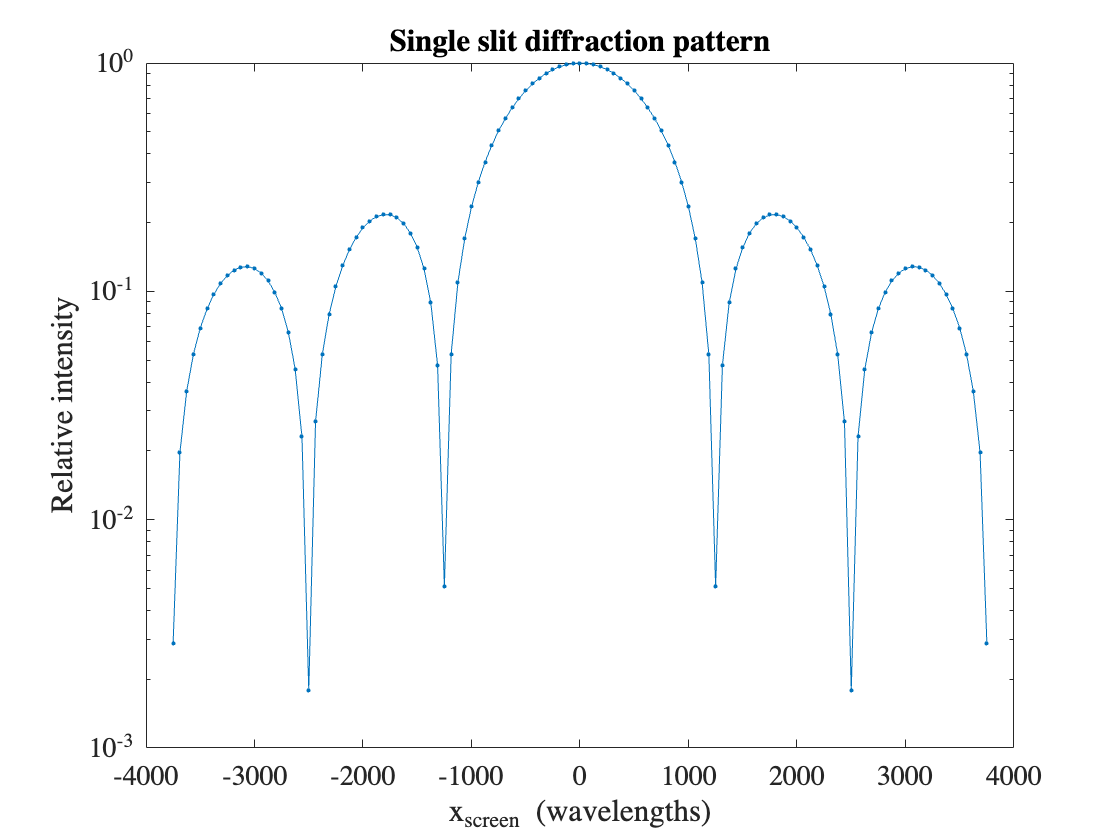

figure
mask=I>0;
semilogy(xprange(mask),I(mask),'.-')
title('Single slit diffraction pattern')
xlabel('x_{screen} (wavelengths)');ylabel('Relative intensity')

For an aperture narrow in x, at large distance, the intensity exhibits a standard diffraction pattern along the x-direction.

## Plot the intensity along the y-axis of the viewing screen. 

sizeQ=size(Q);
midindex=round(sizeQ(1)/2);

Extract the vector of amplitudes along the y-axis of the viewing screen.

q=Q(midindex,:);

Construct the corresponding intensity vector normalized to its maximum value.

I=abs(q);I=I/max(I);

Plot the intensity along the screen y-axis.

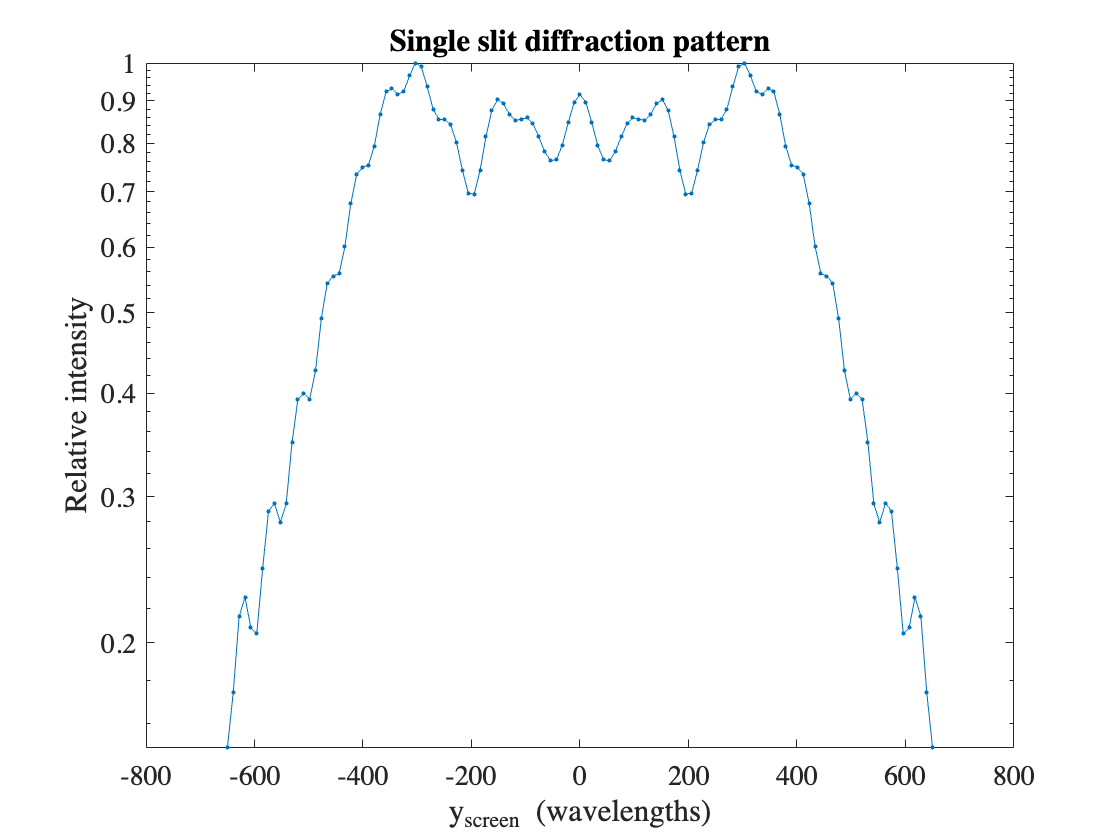

figure
mask=I>0;
semilogy(yprange(mask),I(mask),'.-')
title('Single slit diffraction pattern')
xlabel('y_{screen} (wavelengths)');ylabel('Relative intensity')

For an aperture wide in y, at large distance, the intensity approximates the shape of the aperture but is still modulated by diffraction fringes. 

## Make a 2D color map of the intensity on the viewing screen.

Scale the units to correspond to a nominal laser wavelength.

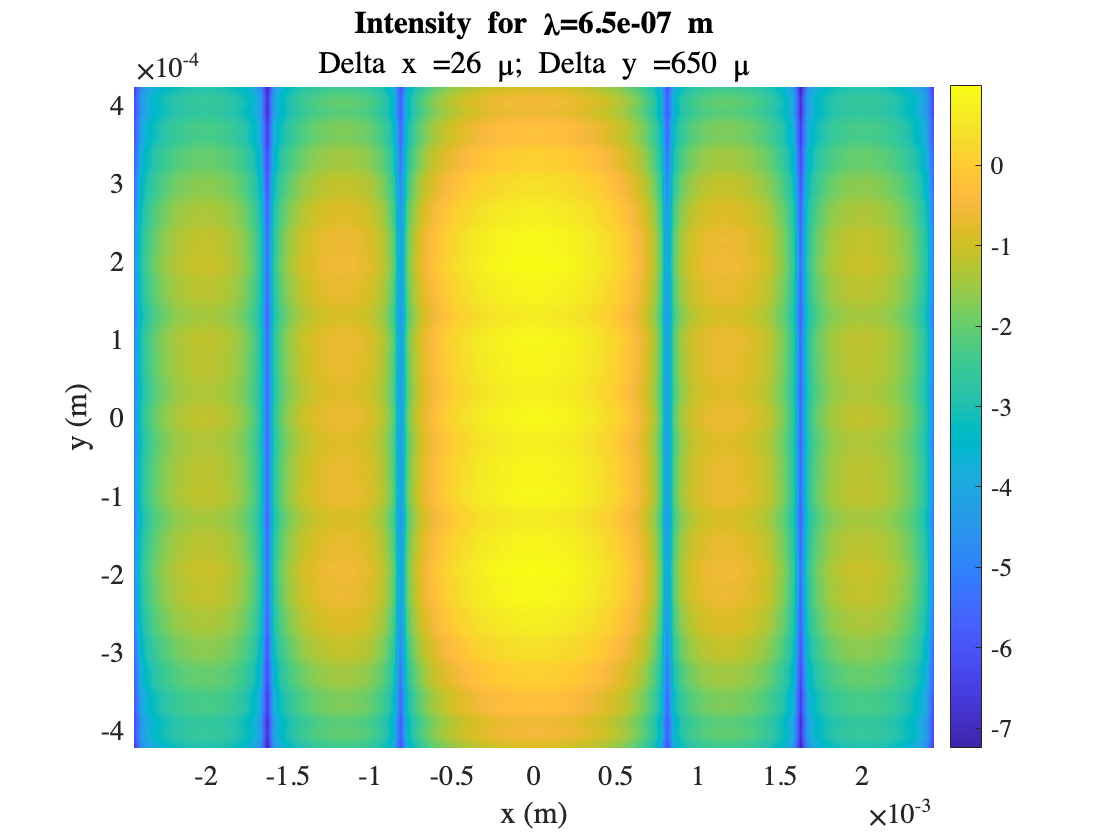

figure
lam=.65e-6;
xprange_meter=xprange*lam;
yprange_meter=yprange*lam;
[X,Y]=ndgrid(xprange_meter,yprange_meter);
pcolor(X,Y,log(abs(Q)));shading interp;
colorbar
%axis equal % Uncomment this line to equalize the x and y scales
title(['Intensity for \lambda=',num2str(lam),' m'])
subtitle(['Delta x =',num2str(2*xmax*lam*1e6),' \mu; Delta y =',num2str(2*ymax*lam*1e6),' \mu'])
xlabel('x (m)');ylabel('y (m)')

license("inuse")

matlab


version

ans = '9.12.0.1884302 (R2022a)'

## Suggestion for further study

To check the accuracy of this calculation, one could compare the results to Rayleigh–Sommerfeld, Fraunhofer, and Kirchoff diffraction models where applicable.

## References

1) Samuel J. Ling, Jeff Sanny, William Moebs, University Physics Volume 3, OpenStax, Sep 29, 2016 [Huygens's Principle](https://openstax.org/books/university-physics-volume-3/pages/1-6-huygenss-principle).

2) David A. B. Miller, ``[Huygens's wave propagation principle corrected](https://www.osapublishing.org/ol/abstract.cfm?uri=ol-16-18-1370),'' Optics Letters, Vol. 16, Issue 18, pp 1370-1372 .